# Flux boundary conditions

set_demo_defaults;

### Exmple problem: Danube-Tisza Interfluve

Here we use the example of the Danube-Tisza Interfluve to discuss **flux boundary conditions**. 

%% Physical properties
cm2m = 1/100;        % cm to m conversion
yr2s = 365*24*60^2;  % yr to s conversion

Length = 85070;      % Distance between Danube and Tisza rivers [m]
Width = 5430;        % Width of segment considered [m]
K =2e-2*cm2m;        % Hydraulic conductivity [m/s]
qp = 1.5*cm2m/yr2s;  % Average annual precipitation [m3/m2/s]
hL = 90;             % Elevation of Danube river[m]
hR = 80;             % Elevation of Tisza river [m]
b = 100;             % Aquifer thickness [m]

% More recently I have changed the BC's
hD = hL; hT = hR;

 The analytic solution for both the head and the flux is


$$h = h_D+\left(\frac{q_pL}{2bK}-\frac{h_D-h_T}{L}\right)x-\frac{q_p}{2bK}x^2$$



$$q=\frac{q_p}{b}\left(x-\frac{L}{2}\right)+\frac{K}{L}\left(h_D-h_T\right)$$
 

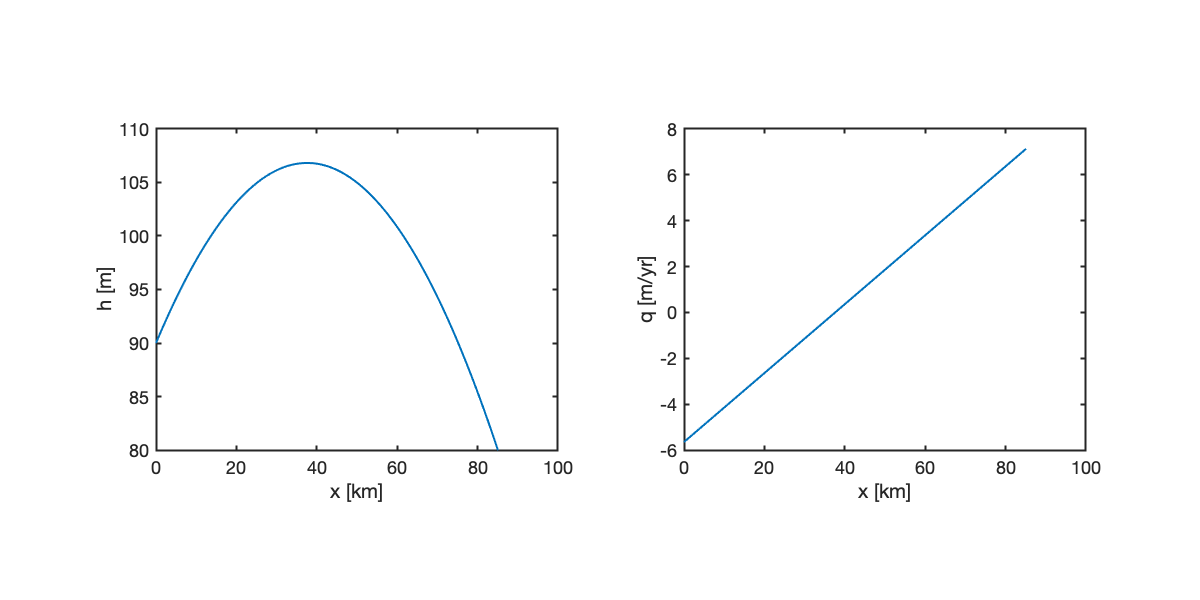

% Analytic solution
xa = linspace(0,Length,1e2);
ha = @(x,qr) hD + (qr*Length/2/b/K-(hD-hT)/Length)*x - qr/2/b/K*x.^2;
qa = @(x,qr) qr/b*(x-Length/2) + K/Length*(hD-hT);

figure('position',[10 10 1200 600])
subplot 121
plot(xa/1e3,ha(xa,qp))
pbaspect([1 .8 1])
xlabel 'x [km]'
ylabel 'h [m]'


subplot 122
plot(xa/1e3,qa(xa,qp)*yr2s)
pbaspect([1 .8 1])
xlabel 'x [km]'
ylabel 'q [m/yr]'

Previously we have imposed the heads of the two rivers as boundary conditions. Here we will evaluate the fluxes from the analytic solution at the boundary and then use them to prescribe the flux across the boundary rather than the head. This does not constrain the head on the boundary so we **must solve for the head on the flux boundary** and requires a different implementation of the boundary condition.

## Flux boundary conditions - Neumann BC's

### Example 1: Neumann BC on left - Dirichlet BC on right

We can now mix both Dirichlet and Neumann boundary conditions.

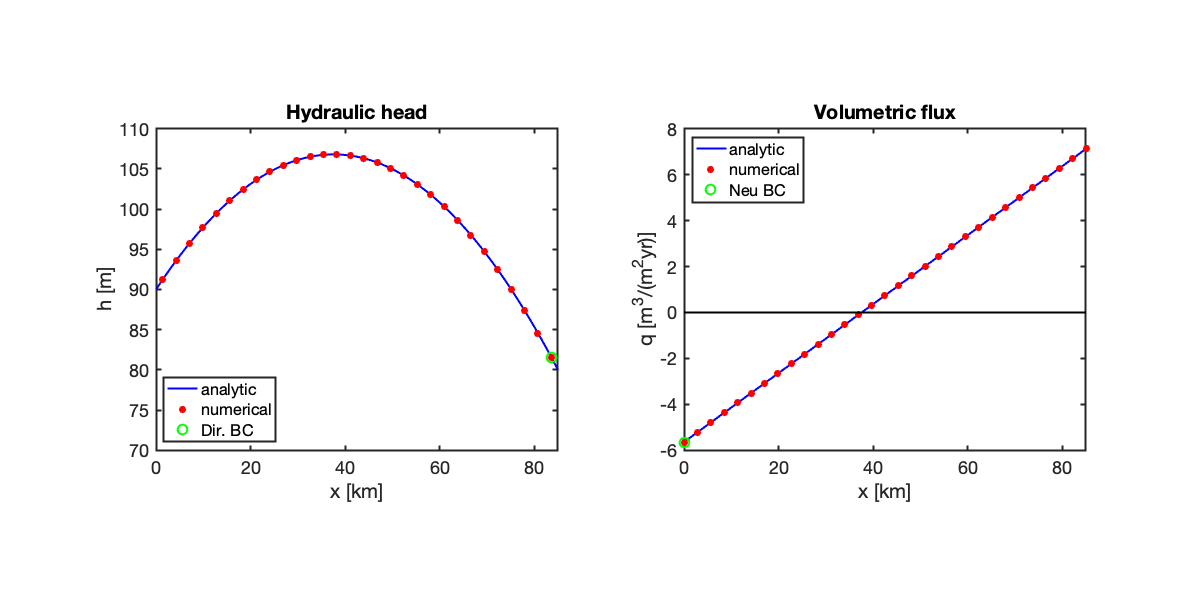

Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = 30;
Grid.ymin = 0; Grid.ymax = 1;  Grid.Ny = 1;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);
L = -D*(K*G); fs = qp/b*ones(Grid.Nx,1);

% Neumann BC (left)
n_in_xmin = 1;          % inward normal at xmin
BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin; % specify the bnd face
BC.qb = n_in_xmin*qa(0,qp);
fn = spalloc(Grid.N,1,length(BC.dof_neu));
fn(BC.dof_neu) = BC.qb.*Grid.A(BC.dof_f_neu)./Grid.V(BC.dof_neu);

% Dirichlet BC (right)
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = ha(Grid.xc(BC.dof_dir),qp);
[B,N] = build_bnd(BC,Grid,I);

%% Solve linear BVP and compute flux
h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,K,G,h,fs,Grid,BC);

%% Plot solution
figure('position',[10 10 1200 600])

subplot 121
plot(xa/1e3,ha(xa,qp),'b-'), hold on
plot(Grid.xc/1e3,h,'r.','markersize',25), hold on
plot(Grid.xc(BC.dof_dir)/1e3,BC.g,'go','markersize',10)
xlabel 'x [km]', ylabel 'h [m]', %legend('analytic','numerical')
legend('analytic','numerical','Dir. BC','location','southwest')
title('Hydraulic head')
xlim([0 Length/1e3]), ylim([70 110])
pbaspect([1 .8 1])

subplot 122
plot(xa/1e3,qa(xa,qp)*yr2s,'b-'), hold on
plot(Grid.xf/1e3,q*yr2s,'r.','markersize',25)
plot(Grid.xf(BC.dof_f_neu)/1e3,qa(0,qp)*yr2s,'go','markersize',10)
plot([0 Length]/1e3,[0 0],'k-')
xlabel 'x [km]', ylabel 'q [m^3/(m^2yr)]' 
legend('analytic','numerical','Neu BC','location','northwest')
title('Volumetric flux')
xlim([0 Length]/1e3)
pbaspect([1 .8 1])

### Example 2: Dirichlet BC on left - Neumann BC on right

We can also apply them the other way around. However with the Neumann conditions the sign of the boundary flux changes!

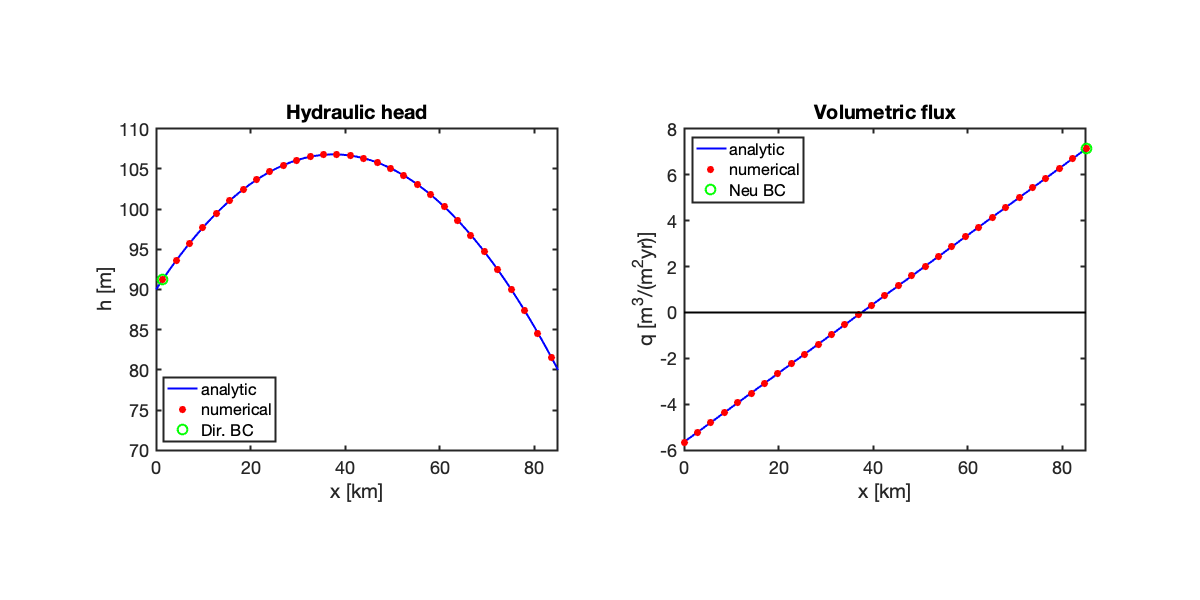

% Dirichlet BC (left)
BC.dof_dir = Grid.dof_xmin;
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g = ha(Grid.xc(BC.dof_dir),qp);

% Neumann BC (right)
n_in_xmax = -1;             % inward normal at xmax
BC.dof_neu = Grid.dof_xmax;
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb = n_in_xmax*qa(Length,qp);
fn = spalloc(Grid.N,1,length(BC.dof_neu));
fn(BC.dof_neu) = BC.qb.*Grid.A(BC.dof_f_neu)./Grid.V(BC.dof_neu);

%% Build boundary conditions
[B,N] = build_bnd(BC,Grid,I);

%% Solve linear BVP and compute flux
h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,K,G,h,fs,Grid,BC);

%% Plot solution
figure('position',[10 10 1200 600])

subplot 121
plot(xa/1e3,ha(xa,qp),'b-'), hold on
plot(Grid.xc/1e3,h,'r.','markersize',25), hold on
plot(Grid.xc(BC.dof_dir)/1e3,BC.g,'go','markersize',10)
xlabel 'x [km]', ylabel 'h [m]', %legend('analytic','numerical')
legend('analytic','numerical','Dir. BC','location','southwest')
title('Hydraulic head')
xlim([0 Length/1e3]), ylim([70 110])
pbaspect([1 .8 1])

subplot 122
plot(xa/1e3,qa(xa,qp)*yr2s,'b-'), hold on
plot(Grid.xf/1e3,q*yr2s,'r.','markersize',25)
plot(Grid.xf(BC.dof_f_neu)/1e3,qa(Length,qp)*yr2s,'go','markersize',10)
plot([0 Length]/1e3,[0 0],'k-')
xlabel 'x [km]', ylabel 'q [m^3/(m^2yr)]' 
legend('analytic','numerical','Neu BC','location','northwest')
title('Volumetric flux')
xlim([0 Length]/1e3)
pbaspect([1 .8 1])